# Plan Coverage Path Using Geodetic Coordinates

Nchute v2

clear
mwLS = [-15.501882, 28.696511 0];
latlim = [-15.502691 -15.501307];
lonlim = [28.695588 28.697498];
geocenter = [mean(latlim) mean(lonlim) 0];

Create a figure containing the map with the longitude and latitude limits.

fig = figure;
g = geoaxes(fig,Basemap="satellite");
geolimits(latlim,lonlim)

pl1lat = [-15.501366 -15.501585 -15.501884 -15.501341]';
pl1lon = [28.696346 28.696565 28.697336 28.697482]';
pl1Poly = [pl1lat pl1lon];

pl2lat = [-15.501825 -15.501880 -15.502537 -15.502517 -15.502558 -15.502154 -15.501997 -15.502354]';
pl2lon = [28.696889 28.697077 28.696817 28.696660 28.696622 28.695788 28.695842 28.696669]';
pl2poly = [pl2lat pl2lon];

cs = uavCoverageSpace(Polygons={pl1Poly,pl2poly},UseLocalCoordinates=false,ReferenceLocation=mwLS);

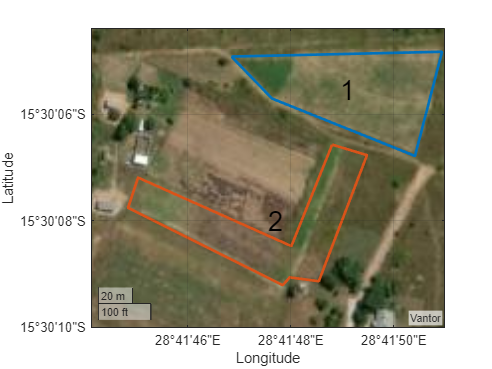

ReferenceHeight = 40;
cs.UnitWidth = 5;
show(cs,Parent=g);

cp = uavCoveragePlanner(cs,Solver="MinTraversal");

Set the takeoff position to a location in the courtyard, then plan the coverage path.

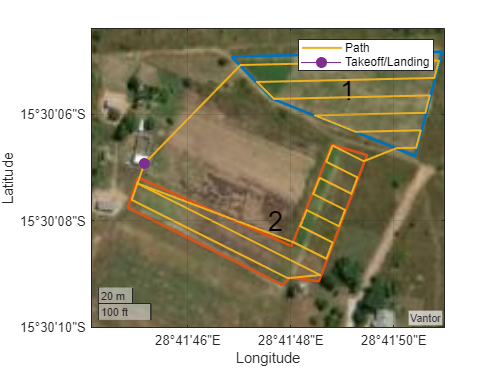

takeoff = [-15.501923 28.695877, 0];
[wp,soln] = plan(cp,takeoff);
hold on
geoplot(wp(:,1),wp(:,2),LineWidth=1.5);
geoplot(takeoff(1),takeoff(2),MarkerSize=25,Marker=".")
legend("","","Path","Takeoff/Landing")
hold off

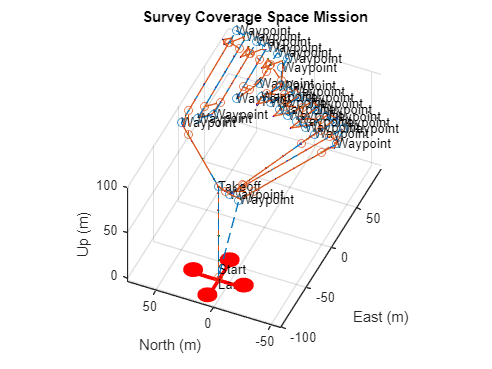

exportWaypointsPlan(cp,soln,"coveragepath.waypoints",ReferenceFrame="NED")
mission = uavMission(PlanFile="coveragepath.waypoints",Speed=5,InitialYaw=90);
exampleHelperSimulateUAVMission(mission,geocenter)